# **PESTools - Example 020 - Fitting XPS spectra**

## PCC

The example shows how to use PESTools to fit the data from an XPS experiment using a model that consists of a linear combination of N curves and a global optimisation method to minimise residuals.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

For external data files, all you need to do is define the **x-axis (binding energy)** and **y-axis (intensity) **and all the fitting tools are available to use. This means you can in principle import any type of data you like, even a text file. To be compatible, all you need to do is define a matlab struct(), for example 'XPS_dat{1}', with **two** fields:

- Define the **x-axis data** as:    XPS_dat{1}**.xdat**

- Deine the **y-axis data **as:     XPS_dat{1}**.int**

close all; clear all;
pp          = plot_props();
data_path   = 'G:\My Drive\GitHub\ADRESSTools\ADRESSTools_Ajax\PESTools_PCC\Examples\Example_Data\';
save_path   = 'G:\My Drive\GitHub\ADRESSTools\ADRESSTools_Ajax\PESTools_PCC\Examples\Example_Data\';

# **XPS Data Processing**

**(A) Loading in the XPS data files**

file_names      = {...
    '020_XPS_In4d_hv=550eV.h5',...
    };
XPS_dat = cell(1,length(file_names));
for i = 1:length(file_names); XPS_dat{i} = load_adress_data(file_names{i}, data_path); end

Loading ARPES data...


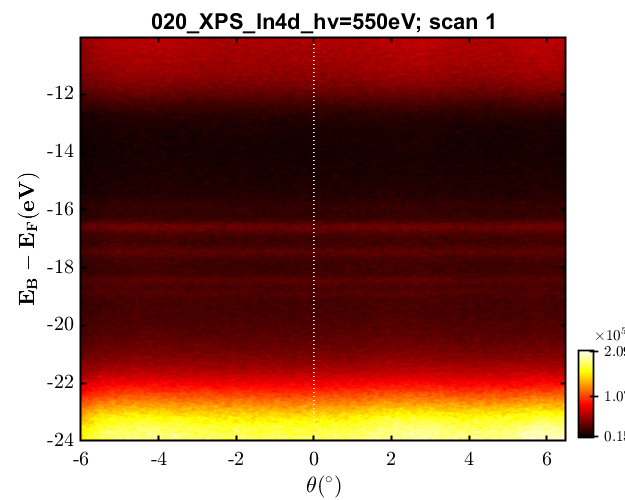

view_data(XPS_dat{1});

**(B) Loading in the Fermi edge reference via gold / copper**

Note, that all XPS data should come with a Fermi-edge reference so that the binding energy scale can be properly calibrated.

% Loading in the data files
file_names_ef      = {...
    '020_XPS_In4d_hv=550eV_EF.h5',...
    };
XPS_ref = cell(1,length(file_names_ef));
for i = 1:length(file_names_ef); XPS_ref{i} = load_adress_data(file_names_ef{i}, data_path); end

Loading ARPES data...


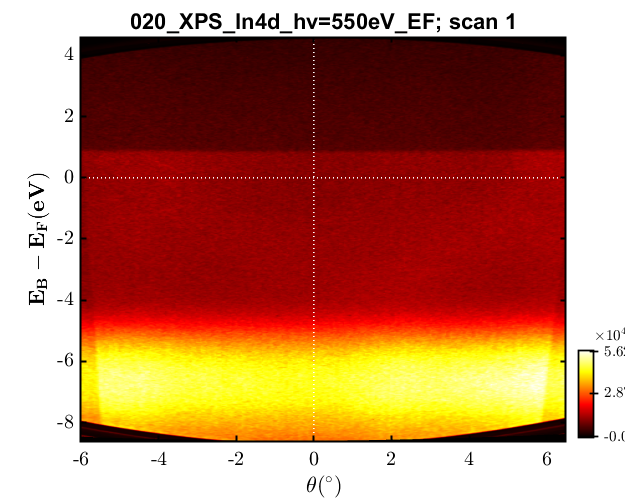

view_data(XPS_ref{1});

**(C) Binding energy alignment to the reference data**

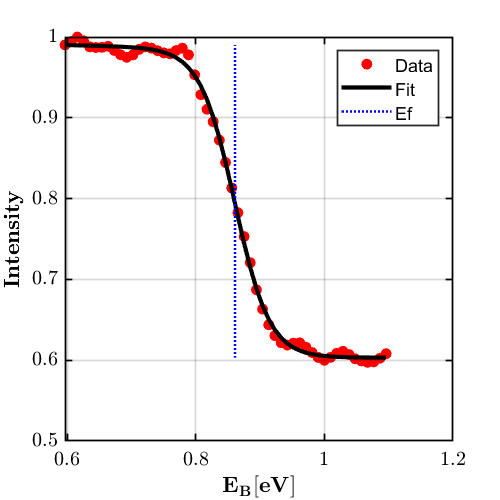

alignType   = "fit2ref";        % either "global", "global shift via scan", "scans", "ref", "ref (per channel)", "fit2ref"
scan_indxs	= [];               % for "global" or "ref" it is empty []. For "scans", it defines the scan indices to perform alignment on.
eWin        = 0.85;                % approximate EF position. Can be a single, constant value. If a vector, it linear interpolates estimates between [firstEF, endEF].
dEWin       = 0.25;              % can be empty []. Single, constant value that defines the width of the EF.
dESmooth    = [];               % can be empty []. Single, constant value that defines Gaussian pre-smoothing energy width.
feat        = 'edge';           % either 'edge' or 'peak'. defines the feature to align as a 'peak' instead of the default Fermi 'edge'.
align_args  = {alignType, scan_indxs, eWin, dEWin, dESmooth, feat};
for i = 1:length(XPS_dat)
    XPS_dat{i}  = align_energy(XPS_dat{i}, align_args, XPS_ref{i}); 
end

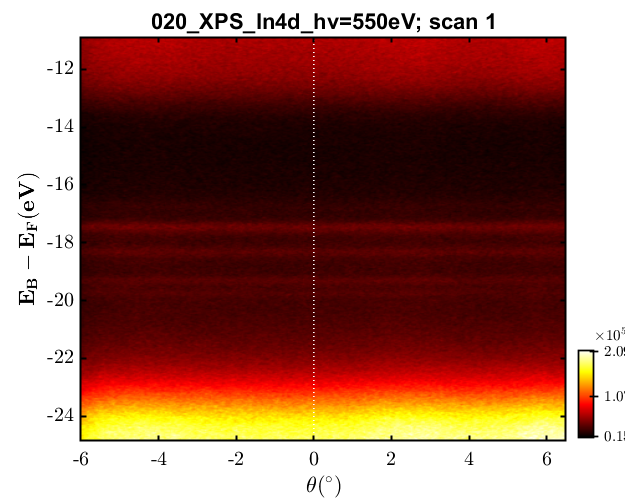

view_data(XPS_dat{1});
line([-1e3, 1e3], [0, 0], 'color', 'c', 'linewidth', 1.5, 'linestyle', '--'); 

**(D) Extract the XPS data by angle-integrating the ARPES spectrum**

- Data cut formation


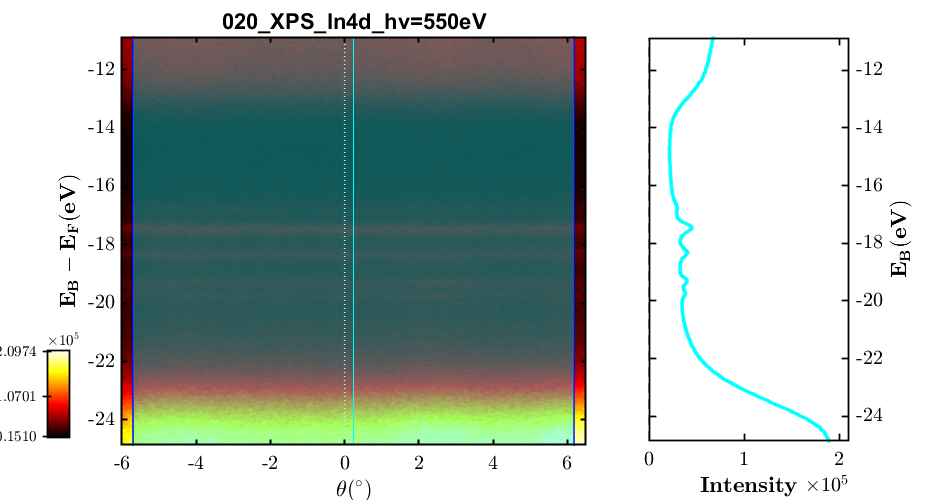

cutWin          = 0.95*[min(XPS_dat{1}.tht(:)), max(XPS_dat{1}.tht(:))];    % Integration window of the cut to be made.
cutN            = 1;                                                        % Single, constant value that determines the total number of line profiles to extract
xps_args        = {cutWin, cutN};
for i = 1:length(XPS_dat)
    [XPS_dat{i}, ~]     = extract_xps(XPS_dat{i}, xps_args);
end

if length(XPS_dat{i}) > 1; XPS_dat = [XPS_dat{:}]; end
view_data(XPS_dat{1});

**(E) Comparing the peak positions vs measurements**

1) x = -17.47 eV, y = 45020.96 


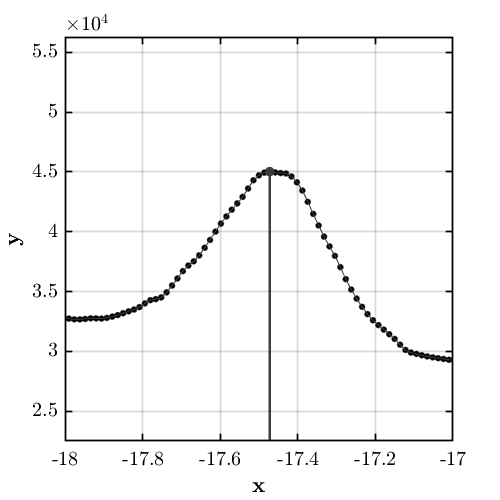

% -- Extracting the energy and intensity of the peak positions
XPS_xVal    = [];
XPS_yVal    = [];
xWin            = -17.5 + [-0.50, 0.50];
for i = 1:length(XPS_dat); [XPS_xVal(i), XPS_yVal(i)] = find_peak_loc(XPS_dat{i}.xdat, XPS_dat{i}.int, xWin, 'spline'); end

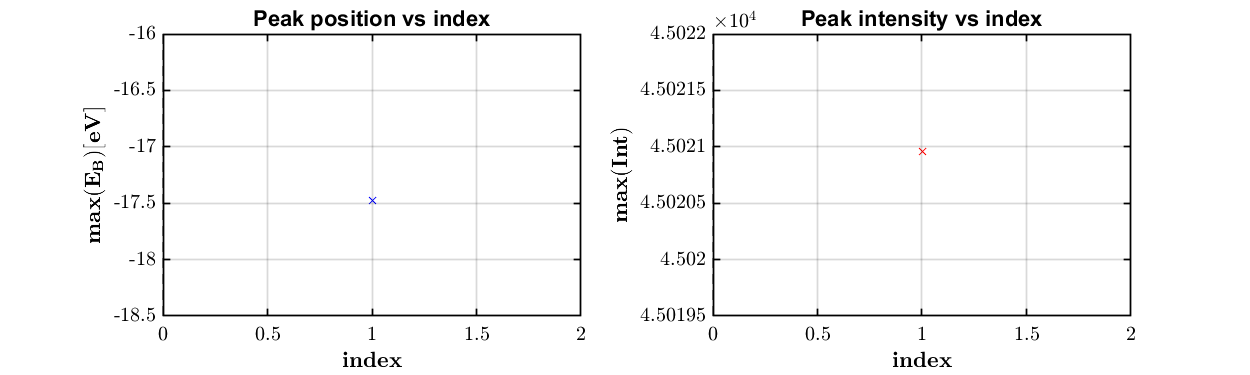

% -- Plotting the comparison
fig1 = figure(); 
fig1.Position(3) = 2.0*500;
fig1.Position(4) = 1.0*300;
% -- Plotting the Peak Eb position vs Photon Energy
subplot(121); hold on;
plot(1:length(XPS_xVal), XPS_xVal, 'bx-');
% - Formatting the figure
% axis padded; 
gca_props(); grid on;
xlabel('$$ \bf  index $$', 'Interpreter', 'latex');
ylabel('$$ \bf  max(E_B) [eV] $$', 'Interpreter', 'latex');
title("Peak position vs index");
% -- Plotting the Peak Intensity vs Photon Energy
subplot(122); hold on;
plot(1:length(XPS_xVal), XPS_yVal, 'rx-');
% - Formatting the figure
% axis padded; 
gca_props(); grid on;
xlabel('$$ \bf  index $$', 'Interpreter', 'latex');
ylabel('$$ \bf  max(Int) $$', 'Interpreter', 'latex');
title("Peak intensity vs index");

**(F) Crop around the region of interest**

As you can see from above, the background is quite large, so we would like to crop the data over the binding energy range of interest. 

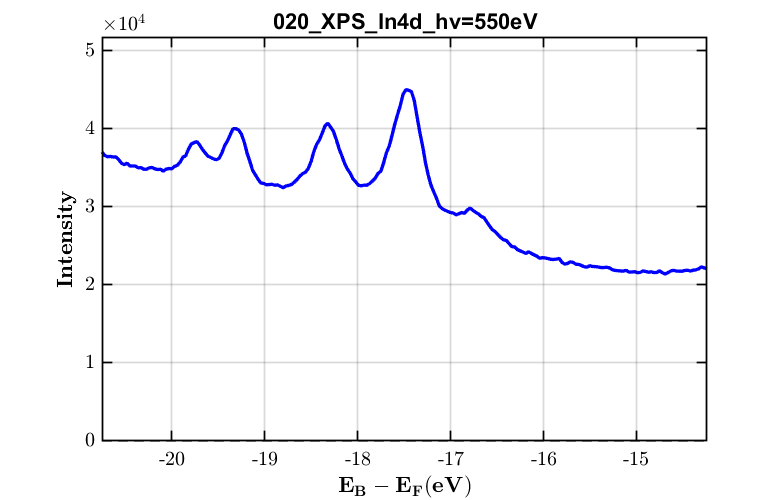

ebLims = -17.5 + [-3.25, 3.25];
for i = 1:length(XPS_dat)
    [~, XPS_dat{i}.xdat, XPS_dat{i}.int] = data_crop2D([], XPS_dat{i}.xdat, XPS_dat{i}.int, [], ebLims);
end
view_xps(XPS_dat{1});

**(G) Normalisation of the XPS spectrum**

One of the most common processing that is done on XPS data is to renormalise the data so that its minimum is at zero and maximum at one. Although not necessary, we do this here as it simplifies the initial conditions of the XPS fitting algorithm to reasonable values of intensities. To normalise the XPS data, we use the 'normalise_xps()' function and define a peak that we treat as the normalisation peak. 

ans = "BE = -17.48 eV, INT = 23601.51"

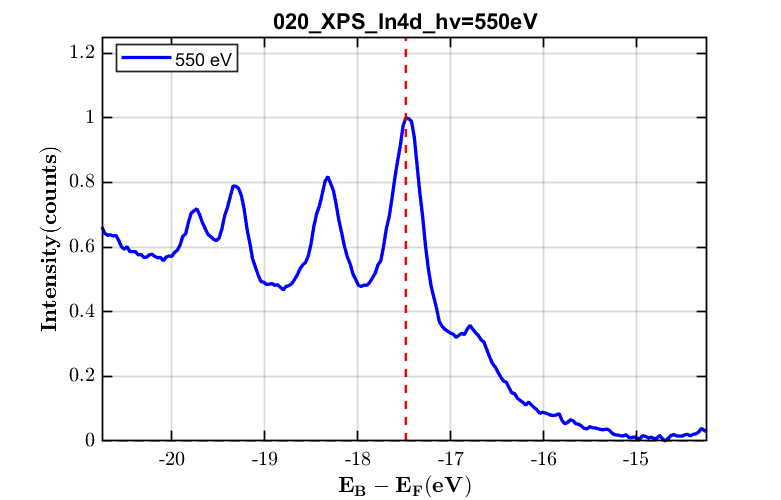

eWin            = -17.5;        % approximate Eb position of a peak in the spectrum to normalise to.
dEWin           = 1.5;          % can be empty []. Single, constant value that defines the width of the approximate Eb position
xpsbgrd_args    = {eWin, dEWin};
for i = 1:length(XPS_dat)
    XPS_dat{i}  = normalise_xps(XPS_dat{i}, xpsbgrd_args);
end

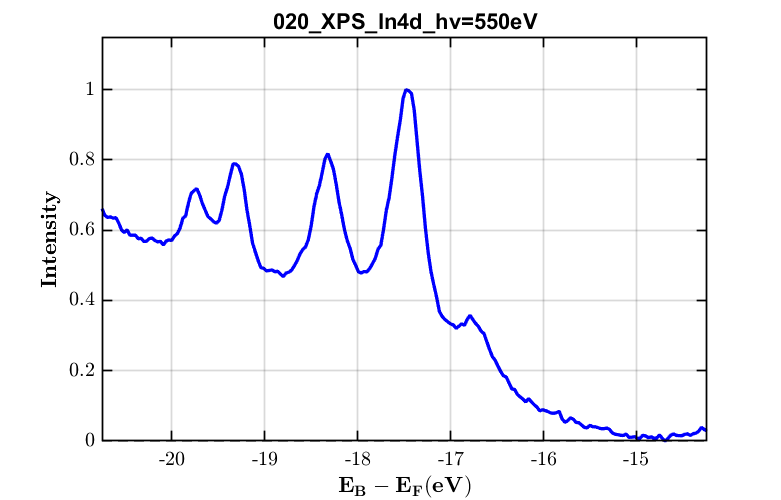

view_xps(XPS_dat{1});

**(H) Final data structure that will be fitted**

ans = struct with fields:
       FileName: '020_XPS_In4d_hv=550eV'
         H5file: '020_XPS_In4d_hv=550eV.h5'
           Type: "Eb(k)"
           meta: [1×1 struct]
       raw_data: [467×391 double]
        raw_tht: [1×391 double]
         raw_eb: [467×1 double]
            deb: 0.0500
             hv: 550
            dhv: 0.0750
           tltM: 0
           thtM: 0
           Temp: 5.5000
      eb_shifts: {[0.8610]}
    eb_ref_file: '020_XPS_In4d_hv=550eV_EF'
             eb: [467×391 double]
            tht: [467×391 double]
        IsoType: "XPS"
       xps_args: {[-5.7000 6.1750]  [1]}
         cutWin: [-5.7000 6.1750]
           cutN: 1
           xdat: [218×1 double]
            int: [218×1 double]
           norm: [1×1 struct]

view_xps(XPS_dat); XPS_dat{1}

# **XPS Fitting Algorithm**

The PESTools functions offer a host of different line-shapes and background that you can use for fitting XPS spectra. Here is a line of all available functions:

- **For PES curves:** **Gaussian**, **Lorentzian**, **Voigt**, **asymmetrical Voigt **and **Doniach-Sunjic** functions are available.

- **For Backgrounds:** **Linear**, **Shirley** and **Offset Shirley** functions are available

The general objective of fitting XPS data is to define an initial photoelectron spectrum that provides a reasonable first guess and then run an optimisation procedure to hone in to the best fit solution. Here, the general procedures are listed below;

- Define the shape and properties of the *N* XPS components to be fitted

- Define the type of background to be used

- Preview the initial conditions of the XPS curve fit model vs data

- If you are happy with the initial guess, use 'xps_solver()' to run the optimisation algorithm

#### 1    :    Define the shape and properties of the PES components to be fitted

iparams = {};
% DEFINING THE TYPES OF CURVES TO BE USED
cTYPE   = ["sGLA";  "sGLA";  "sGLA";  "sGLA"];  % type of curve to use for fitting. Default: "sGLA" ("pGLA", "DS")
% 1 - DEFINING THE INITIAL CONDITIONS OF THE XPS COMPONENTS
BE      = [-17.47;  -17.95;  -16.77; -19.32]; % scalar of the binding energy of PE curve. Each new row gives a new BE component. Make sure sizes are all consistent.
INT     = [0.70;     0.08;   0.18;  0.34];    % scalar of the peak intensity of PE curve.
FWHM    = [0.38;    0.45;   0.49;   0.31];    % scalar of the FWHM of the PE curve.
MR      = [0.69;    0.69;   0.69;   0.60];    % scalar of the Mixing Ratio: 0 for pure Gaussian, 1 is for pure Lorentzian.
LSE     = [-0.85;  -0.85;   -0.85;  -0.42];   % scalar of the binding energy of spin-orbit split PE curve.
LSI     = [0.66;    0.66;   0.66;   0.55];    % scalar of the branching ratio of spin-orbit split PE curve.
LSW     = [0.0;     0.0;    0.0;    0.0];     % scalar of the additional lorentzian width of spin-orbit split PE curve.
ASY     = [0.0;     0.0;    0.0;    0.0];     % scalar of the PE curve asymmetry parameter (usually for metallic systems).
iparams{1} = [BE, INT, FWHM, MR, LSE, LSI, LSW, ASY]; iparams{1}

ans =   -17.4700    0.7000    0.3800    0.6900   -0.8500    0.6600         0         0
  -17.9500    0.0800    0.4500    0.6900   -0.8500    0.6600         0         0
  -16.7700    0.1800    0.4900    0.6900   -0.8500    0.6600         0         0
  -19.3200    0.3400    0.3100    0.6000   -0.4200    0.5500         0         0


% 2 - DEFINING THE UNCERTAINTIES IN THE FIT PARAMETERS
% -- Lower bounds
iparams{2} = iparams{1}; 
iparams{2}(:,1) = iparams{1}(:,1) - 0.25;
iparams{2}(:,2) = iparams{1}(:,2) - 0.25; 
iparams{2}(:,3) = iparams{1}(:,3) - 0.15; 
iparams{2}(:,4) = iparams{1}(:,4) - 0.00; 
iparams{2}(:,5) = iparams{1}(:,5) - 0.15; 
iparams{2}(:,6) = iparams{1}(:,6) - 0.15; 
iparams{2}(:,7) = iparams{1}(:,7) - 0.00; 
iparams{2}(:,8) = iparams{1}(:,8) - 0.00;
iparams{2}

ans =   -17.7200    0.4500    0.2300    0.6900   -1.0000    0.5100         0         0
  -18.2000   -0.1700    0.3000    0.6900   -1.0000    0.5100         0         0
  -17.0200   -0.0700    0.3400    0.6900   -1.0000    0.5100         0         0
  -19.5700    0.0900    0.1600    0.6000   -0.5700    0.4000         0         0


% -- Upper bounds
iparams{3}      = iparams{1}; 
iparams{3}(:,1) = iparams{1}(:,1) + 0.25;
iparams{3}(:,2) = iparams{1}(:,2) + 0.25; 
iparams{3}(:,3) = iparams{1}(:,3) + 0.15; 
iparams{3}(:,4) = iparams{1}(:,4) + 0.00; 
iparams{3}(:,5) = iparams{1}(:,5) + 0.15; 
iparams{3}(:,6) = iparams{1}(:,6) + 0.15; 
iparams{3}(:,7) = iparams{1}(:,7) + 0.00; 
iparams{3}(:,8) = iparams{1}(:,8) + 0.00;
iparams{3}

ans =   -17.2200    0.9500    0.5300    0.6900   -0.7000    0.8100         0         0
  -17.7000    0.3300    0.6000    0.6900   -0.7000    0.8100         0         0
  -16.5200    0.4300    0.6400    0.6900   -0.7000    0.8100         0         0
  -19.0700    0.5900    0.4600    0.6000   -0.2700    0.7000         0         0


#### 2    :    Define the type of background to be used

ibgrnd = {};
% DEFINING THE TYPE OF BACKGROUND TO BE USED
bTYPE   = "Poly";       % type of background to use for fitting. Default: "Poly" ("none", "Shir", "LinShir")
% 1 - DEFINING THE BACKGROUND PARAMETERS
LHS     = -20.5;        % scalar of the START point on the LHS for background
RHS     = -15.5;        % scalar of the END point on the RHS for background
ORD     = 2;            % positive integer of the Polynomial Order for "Poly" background.
LAM     = 0.5;          % scalar for "LinShir" mixing ratio: lambda = 0 is Pure Shirley; lambda = 1 is Pure Linear.
DEL     = 0;            % scalar for the "LinShir" curve offset in binding energy.
BGR     = 0.0088;       % scalar for a constant background to be included in the fit
ibgrnd{1} = [LHS, RHS, ORD, LAM, DEL, BGR]; ibgrnd{1}

ans =   -20.5000  -15.5000    2.0000    0.5000         0    0.0088


% 2 - DEFINING THE UNCERTAINTY IN THE BACKGROUND PARAMETERS
% -- Lower bounds
ibgrnd{2} = abs(0.0.*ibgrnd{1}); 
ibgrnd{2}(:,1) = ibgrnd{1}(:,1) - 0.00;
ibgrnd{2}(:,2) = ibgrnd{1}(:,2) - 0.00;
ibgrnd{2}(:,3) = ibgrnd{1}(:,3) - 0.00;
ibgrnd{2}(:,4) = ibgrnd{1}(:,4) - 0.00;
ibgrnd{2}(:,5) = ibgrnd{1}(:,5) - 0.00;
ibgrnd{2}(:,6) = ibgrnd{1}(:,6) - 0.00;
ibgrnd{2}

ans =   -20.5000  -15.5000    2.0000    0.5000         0    0.0088


% -- Upper bounds
ibgrnd{3} = abs(0.0.*ibgrnd{1}); 
ibgrnd{3}(:,1) = ibgrnd{1}(:,1) + 0.00;
ibgrnd{3}(:,2) = ibgrnd{1}(:,2) + 0.00;
ibgrnd{3}(:,3) = ibgrnd{1}(:,3) + 0.00;
ibgrnd{3}(:,4) = ibgrnd{1}(:,4) + 0.00;
ibgrnd{3}(:,5) = ibgrnd{1}(:,5) + 0.00;
ibgrnd{3}(:,6) = ibgrnd{1}(:,6) + 0.00;
ibgrnd{3}

ans =   -20.5000  -15.5000    2.0000    0.5000         0    0.0088


#### 3    :    Preview the initial conditions of the PES curve fit model vs data

Using the 'view_xps_init_model()' function, you can view your initial guess. 

- **The LHS shows the initial background subtraction method that is used.** In this case, we choose to keep the background fixed during the optimisation process.

- **The RHS shows the initial fit to the XPS spectrum**, where we see it provides quite a good first fit! Each independent XPS component is labelled and colored uniquely. The colored boxes around the peaks show you the approximate area spanned by the uncertainties that are allowed to vary during the convergence of the fit.

- **A plot of the residuals is shown below the XPS spectrum on the RHS. The objective of the 'xps_solver()' or 'xps_solver_n_runs()' algorithms is to minimise the standard deviation of the residuals (which is equal to chi-squared).**

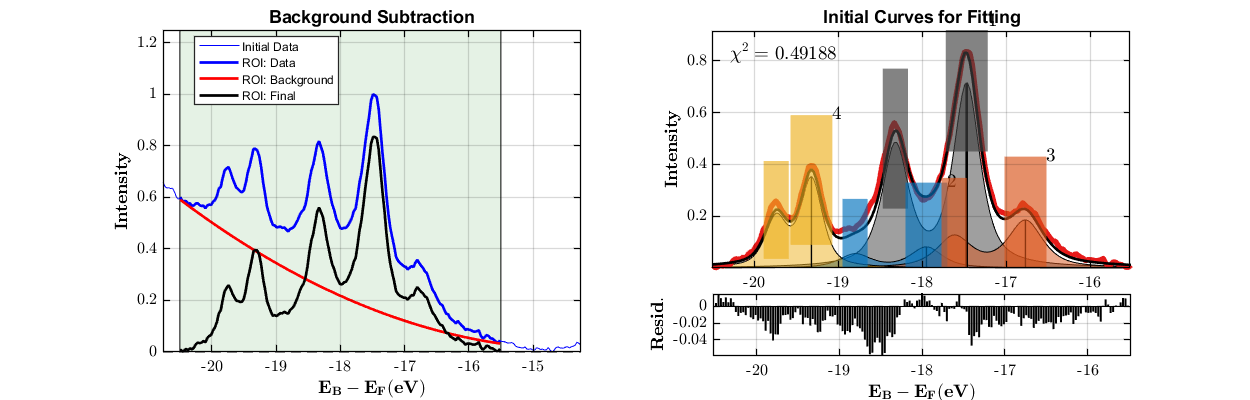

view_xps_init_model(XPS_dat{1}, cTYPE, iparams, bTYPE, ibgrnd);

#### 4    :    Running the solver to find the best fit

The 'xps_solver_n_runs()' function is used to find the optimal solution to the XPS data. Here, we repeat the fitting optimization N independent times using uniformly sampled initial conditions within the bound constraints. This allows a statistical analysis to be performed on the output fit parameters, allowing the variance / uncertainties of each fit parameters to be quantified. Furthermore, repeating the optimisation process N independent times using different initial conditions allows us to be sure we have found the best possible solution, that is independent to the initial conditions defined. 

Run 1 / 20
Local minimum possible. Constraints satisfied.

fmincon stopped because the size of the current step is less than
the value of the step size tolerance and constraints are 
satisfied to within the value of the constraint tolerance.

<stopping criteria details>
Run 2 / 20
Local minimum possible. Constraints satisfied.

fmincon stopped because the 

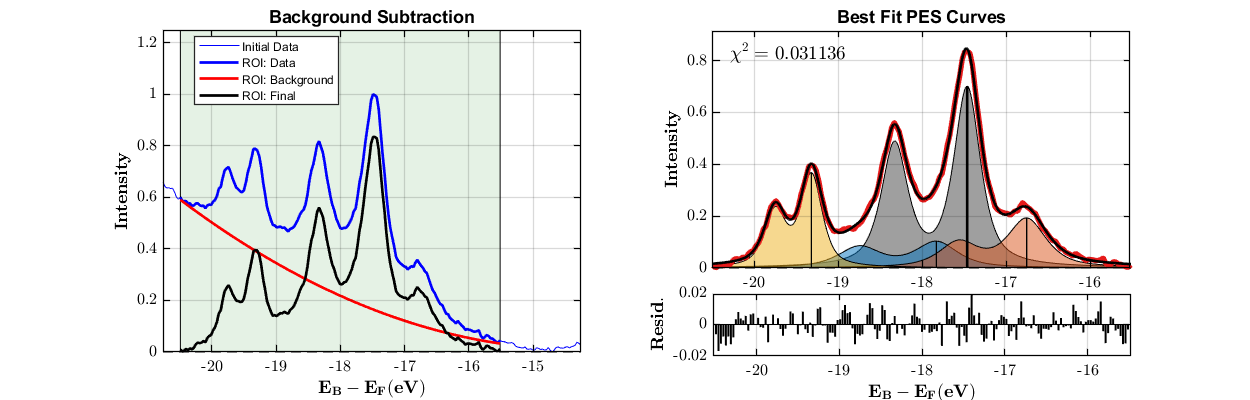

ans = struct with fields:
    solve_type: "fmincon"
         cTYPE: [4×1 string]
    iPESCurves: {[4×8 double]  [4×8 double]  [4×8 double]}
         bTYPE: "Poly"
     iPESBgrnd: {[-20.5000 -15.5000 2 0.5000 0 0.0088]  [-20.5000 -15.5000 2 0.5000 0 0.0088]  [-20.5000 -15.5000 2 0.5000 0 0.0088]}
       nSTATES: 4
          xdat: [218×1 double]
           int: [218×1 double]
             X: [167×1 double]
             D: [167×1 double]
             M: [167×1 double]
             B: [167×1 double]
            DB: [167×1 double]
            MB: [167×1 double]
             R: [167×1 double]
         CHISQ: 0.0311
        MINFUN: 0.0311
           DoF: 20
       bPARAMS: [6×1 double]
           LHS: -20.5000
           RHS: -15.5000
           ORD: 2
           LAM: 0.5000
           DEL: 0
           BGR: 0.0088
            XX: [1000×1 double]
            YY: [1000×1 double]
       cPARAMS: [4×8 double]
           cYY: [1000×4 double]
            BE: [-17.4645 -17.8315 -16.7553 -19.3208]
 

% Each n_run takes around 1 min to optimise the fit, so it may take a while to run this part
n_runs      = 20;
solve_type  = "fmincon";
for i = 1:length(XPS_dat)
    [XPS_dat{i}.fit, XPS_dat{i}.stat]  = xps_solver_n_runs(XPS_dat{i}, cTYPE, iparams, bTYPE, ibgrnd, solve_type, n_runs);
    view_xps_fit(XPS_dat{i}.fit);
    XPS_dat{i}.fit
end

# **Viewing all the best fits and statistical analysis**

#### 5.1    :    Viewing all of the best fits for all the runs performed

The slider bar here can be used to explore through all of the best fit solutions. 

This is very useful when it comes to trying to find the best 'meaningful' solution, or to determine which parameters can be constrained further, if they are giving results that are not matched well with the data.

ans = struct with fields:
    solve_type: "fmincon"
         cTYPE: [4×1 string]
    iPESCurves: {[4×8 double]  [4×8 double]  [4×8 double]}
         bTYPE: "Poly"
     iPESBgrnd: {[-20.5000 -15.5000 2 0.5000 0 0.0088]  [-20.5000 -15.5000 2 0.5000 0 0.0088]  [-20.5000 -15.5000 2 0.5000 0 0.0088]}
       nSTATES: 4
          xdat: [218×1 double]
           int: [218×1 double]
             X: [167×1 double]
             D: [167×1 double]
             M: [167×1 double]
             B: [167×1 double]
            DB: [167×1 double]
            MB: [167×1 double]
             R: [167×1 double]
         CHISQ: 0.0311
        MINFUN: 0.0311
           DoF: 20
       bPARAMS: [6×1 double]
           LHS: -20.5000
           RHS: -15.5000
           ORD: 2
           LAM: 0.5000
           DEL: 0
           BGR: 0.0088
            XX: [1000×1 double]
            YY: [1000×1 double]
       cPARAMS: [4×8 double]
           cYY: [1000×4 double]
            BE: [-17.4645 -17.8315 -16.7553 -19.3208]
 

nScan = 1; nFit = 4; 
view_xps_fit(XPS_dat{nScan}.stat.fit{nFit}); XPS_dat{nScan}.stat.fit{nFit}

#### 5.2    :    Plotting a statistical analysis of all the fit parameters

Here, we plot how each fit parameter varies as a function of the run number.

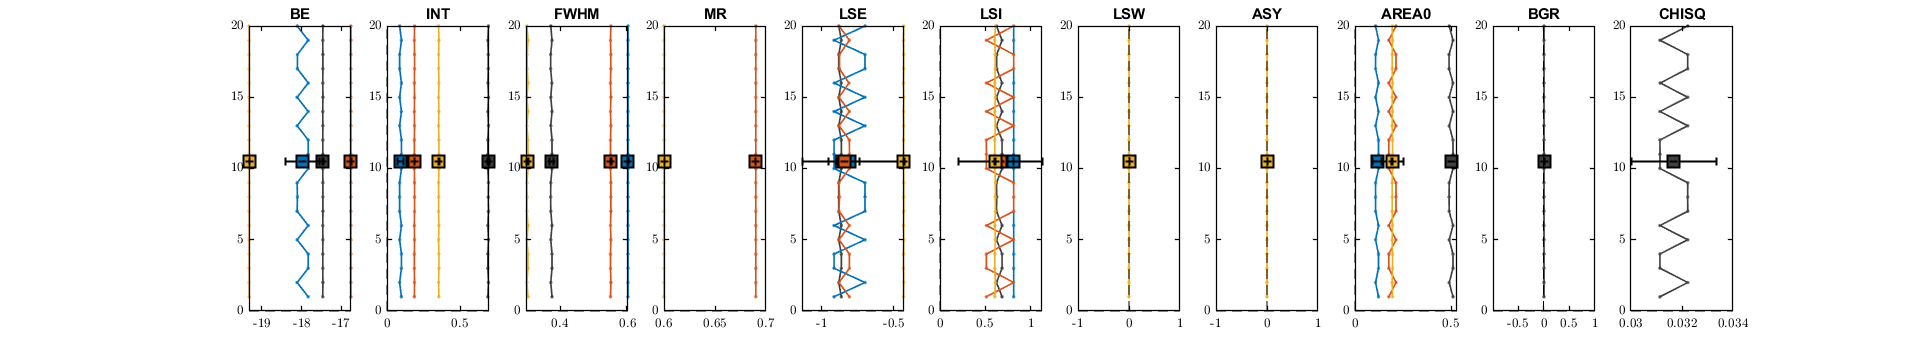

ans = struct with fields:
          n_runs: [1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20]
             fit: {20×1 cell}
          params: {11×1 cell}
           CHISQ: [20×1 double]
    params_label: {'BE'  'INT'  'FWHM'  'MR'  'LSE'  'LSI'  'LSW'  'ASY'  'AREA0'  'BGR'  'CHISQ'}
         CHISQmu: 0.0317
        CHISQerr: 0.0017
              BE: [20×4 double]
            BEmu: [-17.4631 -17.9700 -16.7562 -19.3216]
           BEerr: [0.0040 0.4161 0.0027 0.0024]
             INT: [20×4 double]
           INTmu: [0.6887 0.0922 0.1869 0.3525]
          INTerr: [0.0058 0.0186 0.0017 0.0029]
            FWHM: [20×4 double]
          FWHMmu: [0.3741 0.6000 0.5490 0.3037]
         FWHMerr: [0.0056 2.6311e-05 0.0017 0.0043]
              MR: [20×4 double]
            MRmu: [0.6900 0.6900 0.6900 0.6000]
           MRerr: [6.6613e-16 6.6613e-16 6.6613e-16 3.3307e-16]
             LSE: [20×4 double]
           LSEmu: [-0.8740 -0.8078 -0.8446 -0.4303]
          LSEerr: [0.0274 0.3233 0.106

nScan = 1;
view_stat_params(XPS_dat{nScan}.stat.params, XPS_dat{nScan}.stat.params_label); XPS_dat{nScan}.stat

#### 5.3    :    Plotting a histogram analysis of all fit parameters

Here, we plot a histogram of each fit parameter, which will reflect the statistical model associated with the fit variable. There are two general forms the histogram may take:

- A **Normal Distribution, **which peaks in the middle and gradually decreases towards both ends of axis. This is usually associated with experimental uncertainties in measurements, so we should expect each variable to yield a Normal distribution.

- A **Uniform Distribution, **which stays constants and where all points in range are equally likely to occur. 

nScan = 1;
nParam = 1; 
fprintf(XPS_dat{nScan}.stat.params_label{nParam}); 

BE

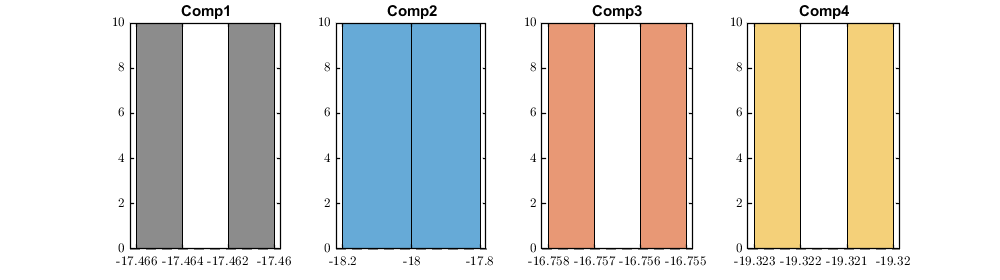

view_stat_hist(XPS_dat{nScan}.stat.params{nParam}, {'Comp1', 'Comp2', 'Comp3', 'Comp4'});

#### 5.4    :    Plotting a cluster analysis of all fit parameters

Here, we plot a cluster analysis of each fit parameter, so we can identify if there is only a single physical solution, or if there are multiple 'clusters' of solutions. A best fit 2D Gaussian distribution is used to fit the cluster data.

nScan = 1;
nParam = 1; 
fprintf(XPS_dat{nScan}.stat.params_label{nParam}); 

BE

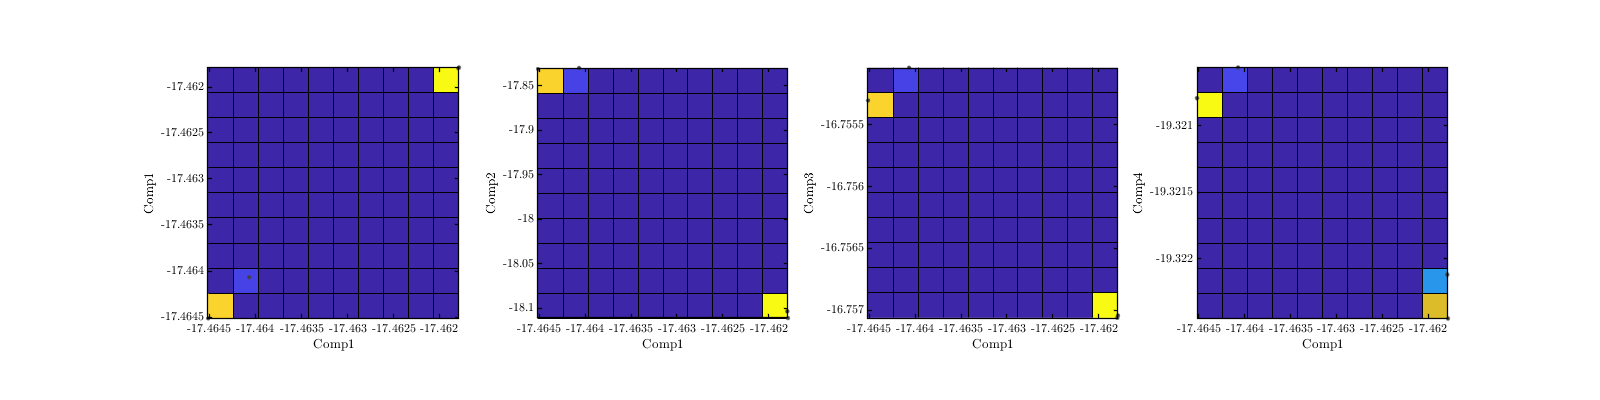

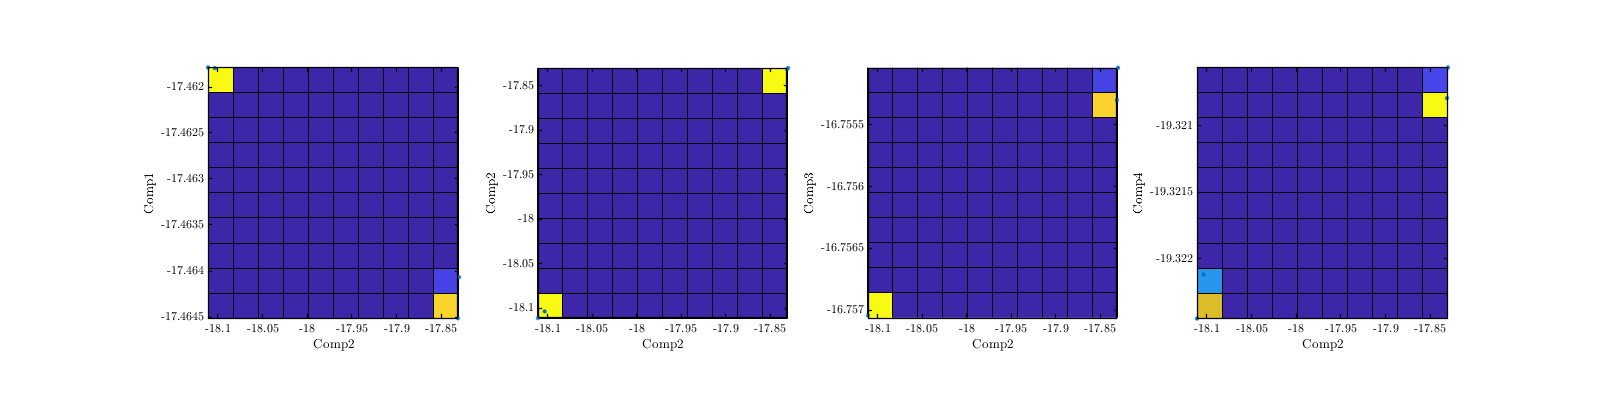

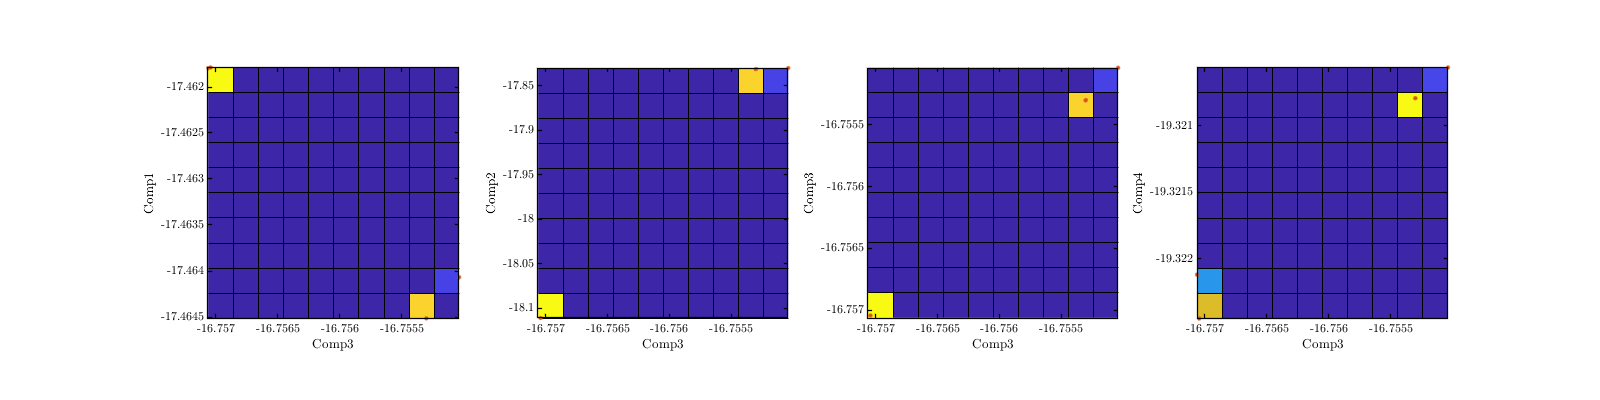

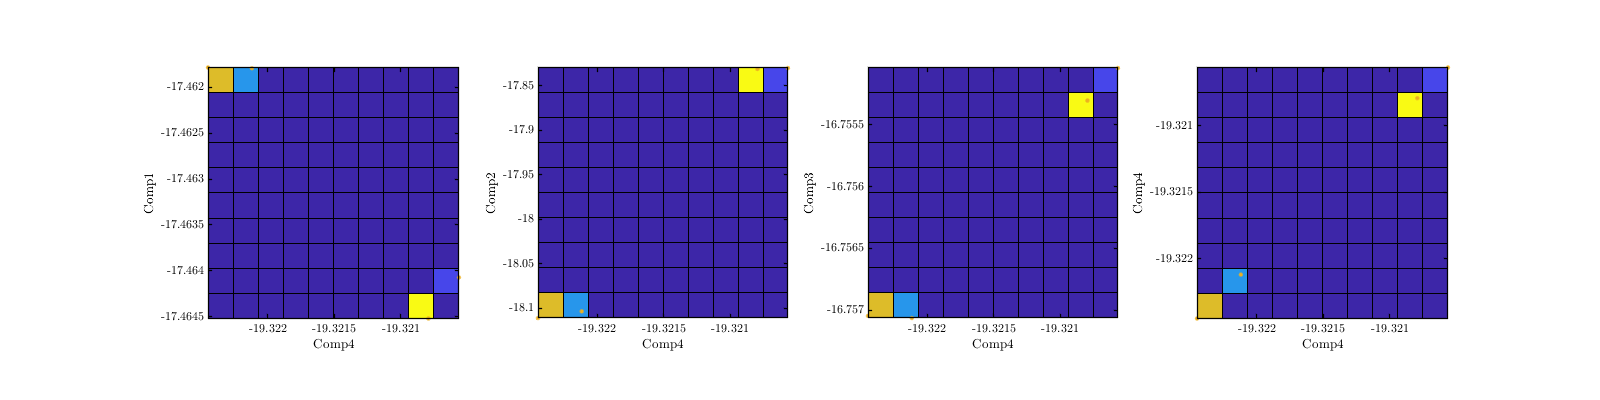

view_stat_cluster(XPS_dat{nScan}.stat.params{nParam}, {'Comp1', 'Comp2', 'Comp3', 'Comp4'});